Distanza tra colori

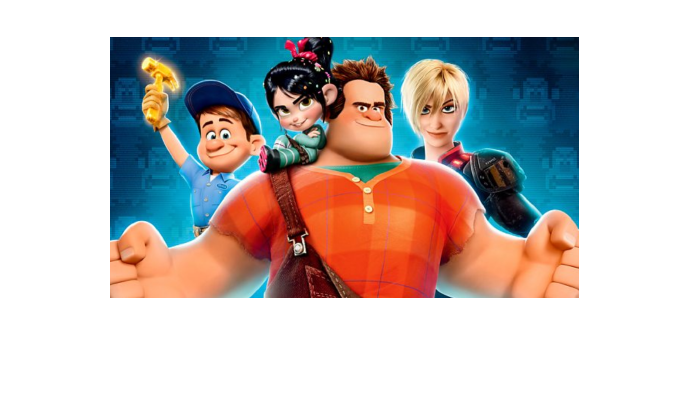

I = imread('./ralph.png');
figure, imshow(I)

Scelgo un punto

p = [0 0 255];

Calcolo la distanza (colore) da p a tutti i pixel:

D = zeros(size(I,1),size(I,2));
for x=1:size(I,1)
    for y=1:size(I,2)
        D(x,y) = norm(p(:) - double(squeeze(I(x,y,:))));
    end
end
D = (D - min(D(:))) ./ (max(D(:)) - min(D(:)));

Visualizzo le distanze da p

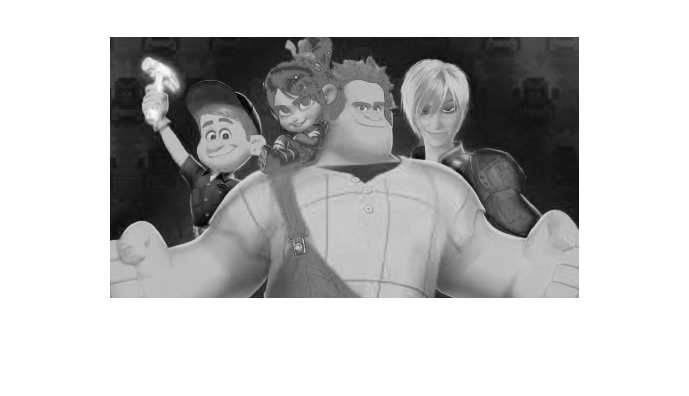

imshow(D)

Definisco l'adiacenza per il punto p

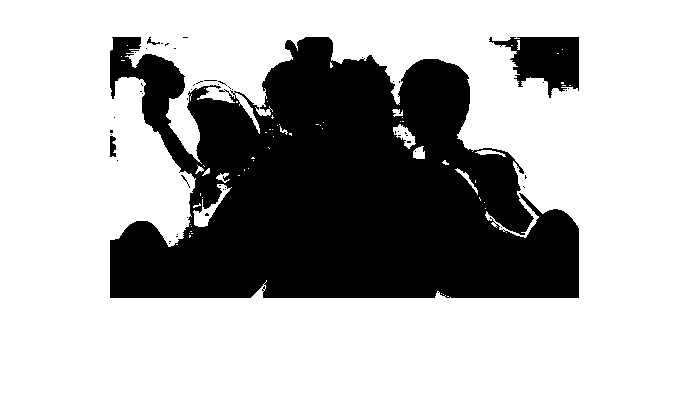

A = D;
t = 0.2;
A(D<=t) = 1;
A(D>t) = 0;

figure, imshow(A)